# Excitation Generation

disp('<Running Part1_03_Excitation_Generation.mlx>')

<Running Part1_03_Excitation_Generation.mlx>



WindowExcitation = zeros(seg,nDOF); % excitation for one window

% container for excitation
Excitation_AV = [];
Excitation_EQ = [];
Excitation_IP = [];
Excitation_WD = [];

% to restore downsampled data, currently not in use
Excitation_AV_DS = []; 
Excitation_EQ_DS = [];
Excitation_IP_DS = [];
Excitation_WD_DS = []; 

## 1 Ambient Vibration

disp('AV Generation and Response Simulation')

AV Generation and Response Simulation


     1



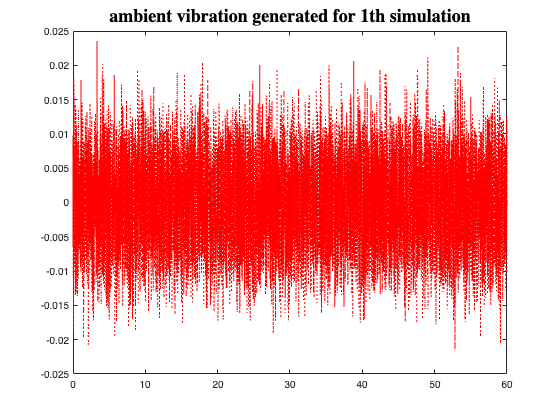

     2



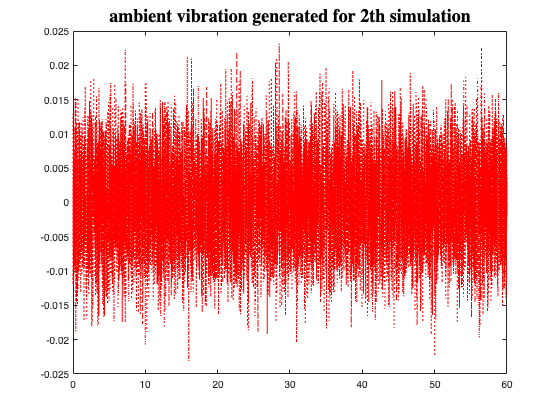

     3



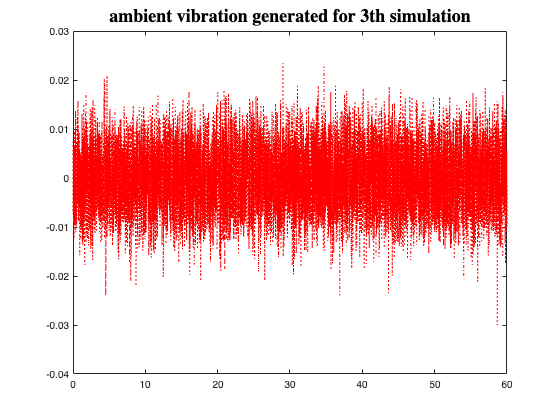

     4



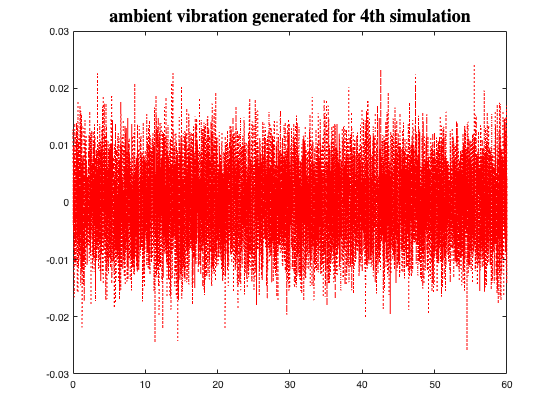

     5



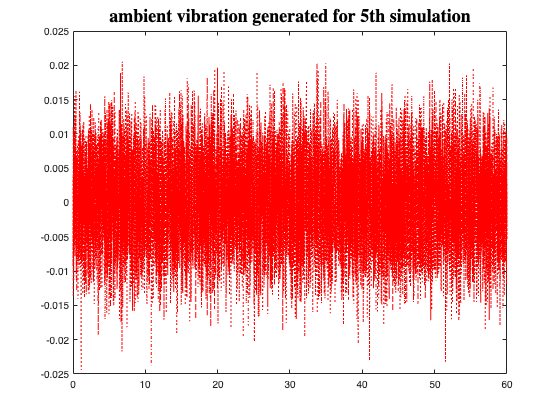

for i = 1:NumSeg
    % current progress
    if i/(NumSeg/5) == fix(i/(NumSeg/5))
        disp(i)
    end

    % add Gaussian white noise
    for j = 1:nDOF
        WindowExcitation(:,j) = wgn(seg,1,power);
        tmp_ns_lvl = mean(abs(WindowExcitation(:,j)));
        tmp_fac = target_noise_level/tmp_ns_lvl;
        WindowExcitation(:,j) = tmp_fac * WindowExcitation(:,j);
    end
    
    % check data
    if flg_img_show == 1 && i/(NumSeg/5) == fix(i/(NumSeg/5))
        figure
        plot(TimeSeries,WindowExcitation(:,1),'r:')
        Title = ['ambient vibration generated for ',num2str(i),'th simulation'];
        title(Title,'FontName','Times New Rome','FontSize',18)
    end
    
    % integration
    Excitation_AV(i,j,:) = squeeze(WindowExcitation(:,j));  
end


disp('Ambient Vibration Generation Finished')

Ambient Vibration Generation Finished



    size(Excitation_AV)

ans =            5           5       12000


    fn_tmp = 'Excitation_AV.mat';
    save(fn_tmp,'Excitation_AV')

## 2 Earthquake Generation

disp('EQ Generation and Response Simulation')

EQ Generation and Response Simulation


     1



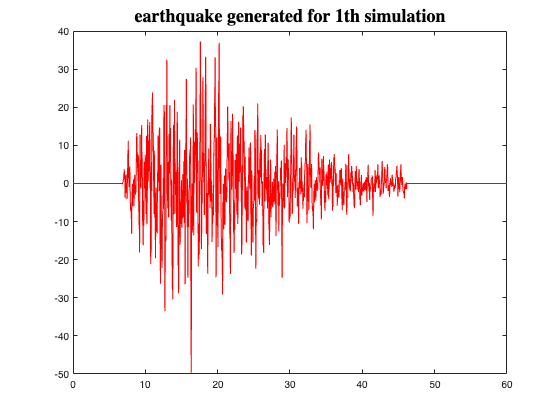

     2



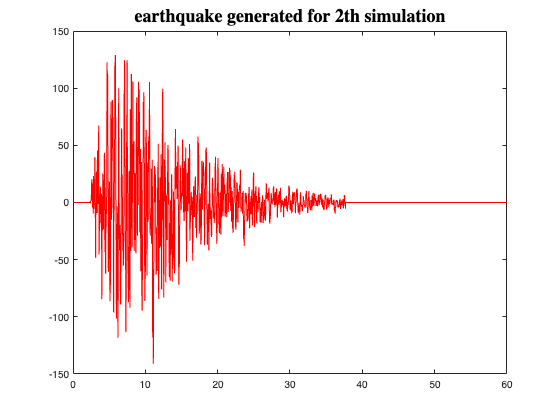

     3



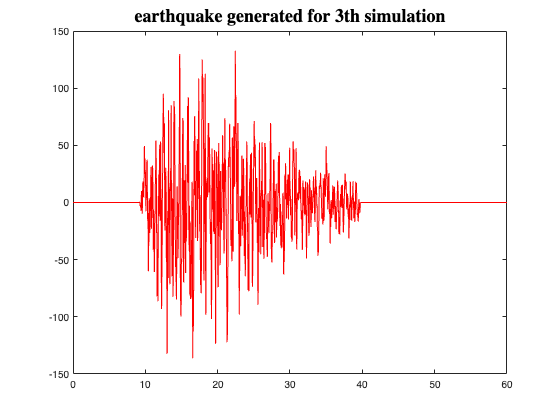

     4



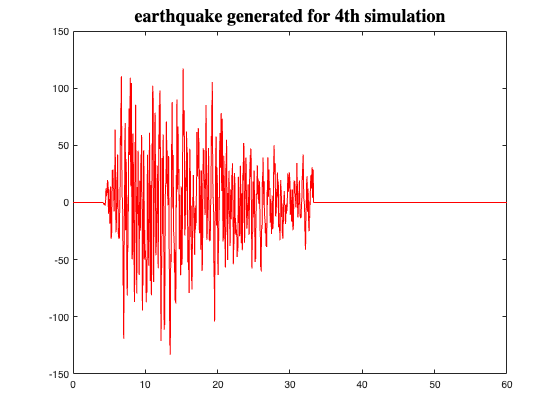

     5



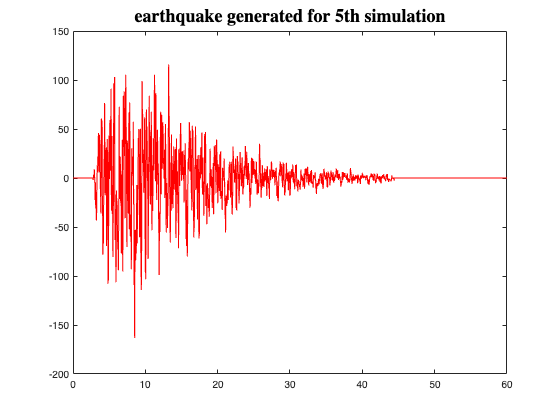

for i = 1:NumSeg
    % current progress
    if i/(NumSeg/5) == fix(i/(NumSeg/5))
        disp(i)
    end

    % input excitation generation
    EqDur = (0.4 + rand(1) * 0.6) * 0.8 * window;
    omegag = omegag_base * (1+0.5*(rand(1)-0.5));
    zetag = zetag_base * (1+0.5*(rand(1)-0.5));
    S0 = S0_base * (1+0.5*(rand(1)-0.5));
    fac_time = fac_time_base * (1+0.5*(rand(1)-0.5));
    pos_time1 = pos_time1_base * (1+0.5*(rand(1)-0.5));
    pos_time2 = pos_time1 + 0.4 * rand(1);%pos_time2_base * (1+0.5*(rand(1)-0.5));
    if pos_time1 > pos_time2
        tmp_pos = pos_time1;
        pos_time1 = pos_time2;
        pos_time2 = tmp_pos;
    end

    [EqData,EqTime,TailVal] = EqSimulation(SimStep,EqDur,omegag,zetag,S0,fac_time,pos_time1,pos_time2);

    eqlen = length(EqData);
    eqloc = randi([1,round((seg-eqlen)/2)],1);

    TempEqData = zeros(seg,1);
    for k = 1:eqlen
        TempEqData(eqloc - 1 + k) = EqData(k);
    end
     
    WindowExcitation = factoreq * TempEqData;

    % check data 
    if flg_img_show == 1 && i/(NumSeg/5) == fix(i/(NumSeg/5))
        figure
        plot(TimeSeries,WindowExcitation(:,1),'r')
        Title = ['earthquake generated for ',num2str(i),'th simulation'];
        title(Title,'FontName','Times New Rome','FontSize',18)
    end

    % integration
    Excitation_EQ(i,j,:) = WindowExcitation; 

end


disp('Earthquake Generation Finished')

Earthquake Generation Finished



size(Excitation_EQ)

ans =            5           5       12000


fn_tmp = 'Excitation_EQ.mat';
save(fn_tmp,'Excitation_EQ')


## 3 Impact Generation

disp('IP Generation and Response Simulation')

IP Generation and Response Simulation


     1



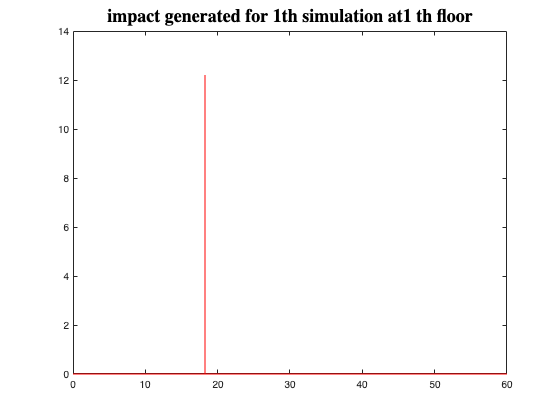

     2



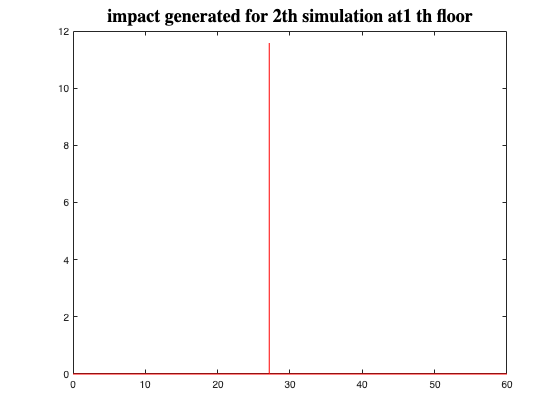

     3



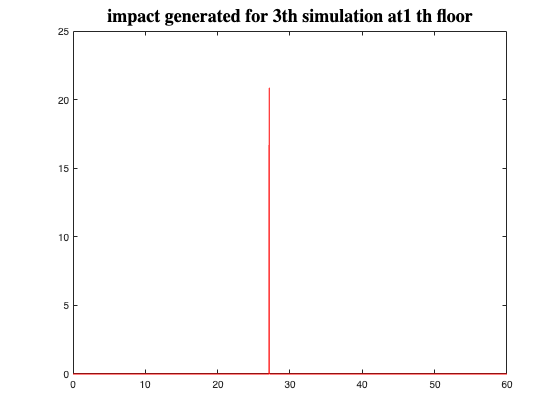

     4



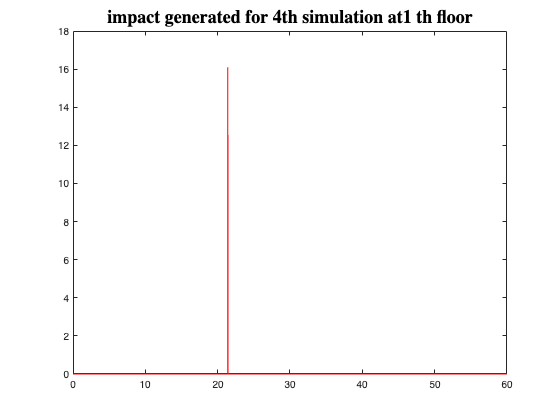

     5



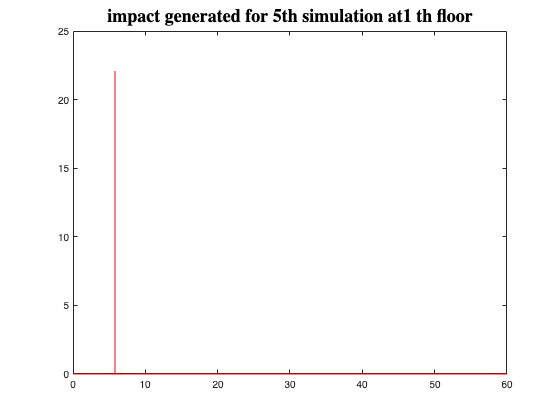

for i = 1:NumSeg
    % current progress
    if i/(NumSeg/5) == fix(i/(NumSeg/5))
        disp(i)
    end

    WindowExcitation = zeros(seg,nDOF);

    % input excitation generation
    ipfloor = 1; %randi([1,5],1);
    iploc = randi([1, floor(0.75*seg)],1);
    ipintense = sign(rand(1)-0.5) * ImpactBaseline * (0.5 + rand(1)); % random direction / 0.5 - 1.5 times baseline

    WindowExcitation(iploc,ipfloor) = ipintense;

    % check data
    if flg_img_show == 1 && i/(NumSeg/5) == fix(i/(NumSeg/5))
        figure
        plot(TimeSeries,WindowExcitation(:,ipfloor),'r-')
        Title = ['impact generated for ',num2str(i),'th simulation at',num2str(ipfloor),' th floor' ];
        title(Title,'FontName','Times New Rome','FontSize',18)
    end
    
    % integration
    for j = 1:nDOF
        Excitation_IP(i,j,:) = squeeze(WindowExcitation(:,j)); 
    end
end


disp('Impact Generation Finished')

Impact Generation Finished



size(Excitation_IP)

ans =            5           5       12000


fn_tmp = 'Excitation_IP.mat';
save(fn_tmp,'Excitation_IP')


## 4 Strong Wind Generation

disp('WD Generation and Response Simulation')

WD Generation and Response Simulation


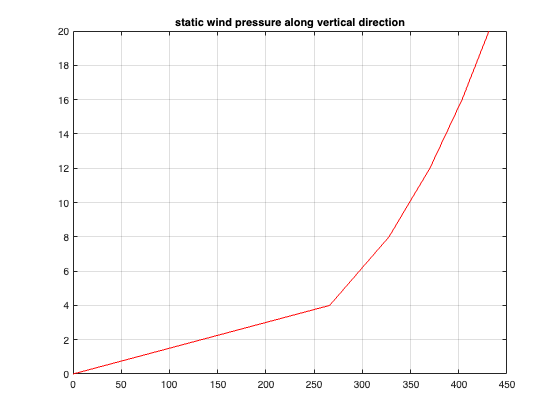

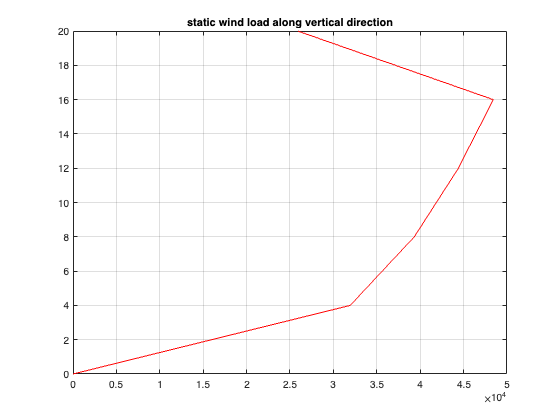

% wind load can be simulated as two components, i.e., the static (steady) component
% and dynamic (pulsating) component

% Parameters Assumptions

% Geometry Parameters   
BuildingWidth = 30*ones(nDOF,1);% Width

% standard interstorey height
h = 4; %m 

% heights of areas that winds apply
DH = [h*ones(nDOF-1,1) ; h/2]; 

% heights of mass lumps
H = h*[1:1:nDOF]; 

% Area of the wall facing the wind
Area = BuildingWidth.*DH; 

% Wind Related Parameters
ur = 1.1; % recurrence coefficient

%structure shape coefficient, front and back sides of the building
us = 0.8 + 0.5; 

% height coefficient
uz = zeros(nDOF,1);
for i = 1:nDOF
    uz(i) = (H(i)/10)^0.3;
end

% air density
rho = 1.225;% kg/m^3

% basic wind speed at 10m high
v0 = 20;% m/s 

% basic wind pressure
w0 = (1/2)*rho*v0^2; 


%% I Simulation of the static component
% static wind pressure 
ws = ones(nDOF,1); 
for i = 1:nDOF
    ws(i) = ur*us*uz(i)*w0;
end

ExcitationWindStatic = ones(seg,1)* (ws.*Area)'; % size = seg x nDOF
if flg_img_show == 1
    figure
    plot([0;ws],[0;H'],'r')
    title('static wind pressure along vertical direction')
    grid on

    figure
    plot([0;ExcitationWindStatic(1,:)'],[0;H'],'r')
    title('static wind load along vertical direction')
    grid on
end

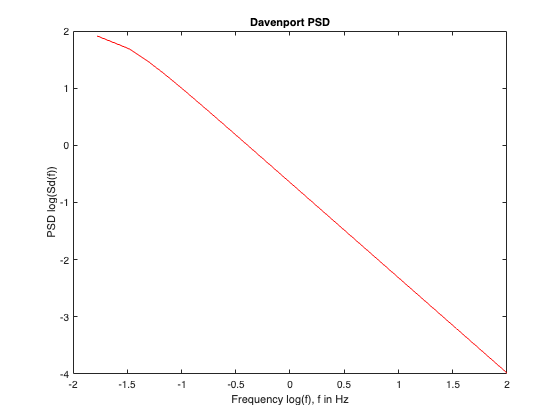


% II Simulation of the dynamic component - Auto Rgression Method & Davenport PSD
%%%%%ExcitationWindDynamic = zeros(nDOF,NumFrame);

%% Parameters for Pulsating Wind Simulation

alpha = 0.16;% roughness factor

K = 0.00215; % coefficient in Davenport PSD: for roughness alpha (0.12 0.16 0.22 0.30), the K values are 0.00129 0.00215 0.00464 0.01291 respectively

f_nyquist = 1/(2*SimStep); % Nyquist frequency Nyquist frequency is the highest frequency that can be represented in a digital signal or sampled data system.
% It is defined as half of the sampling rate, which is also known as the Nyquist rate. If the signal contains frequencies higher than the Nyquist frequency, 
% these frequencies will not be correctly represented in the sampled data and will cause aliasing distortion.

df = f_nyquist / floor(seg/2); % frequency resolution

fv = [0:df:f_nyquist]'; % frequency vector

x0 = 1200*fv/v0; % x0 in Darvenport PSD, refer to formula (13)

Sdf = 4*K*v0^2*x0.^2./(fv.*(1+x0.^2).^(4/3)); % discretized Davenport PSD

Sdf(1) = 0; % as f(1) = 0, Sdf(1) should be correctified accordingly

% check the PSD
if flg_img_show == 1
    figure
    plot(log10(fv(1:end)),log10(Sdf(1:end)),'r-')
    title('Davenport PSD')
    xlabel('Frequency log(f), f in Hz')
    ylabel('PSD log(Sd(f))')
end

     5



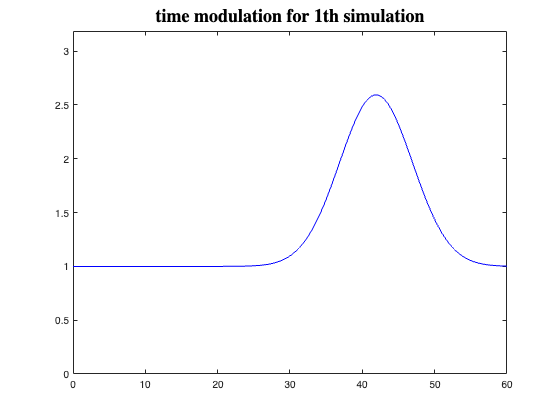

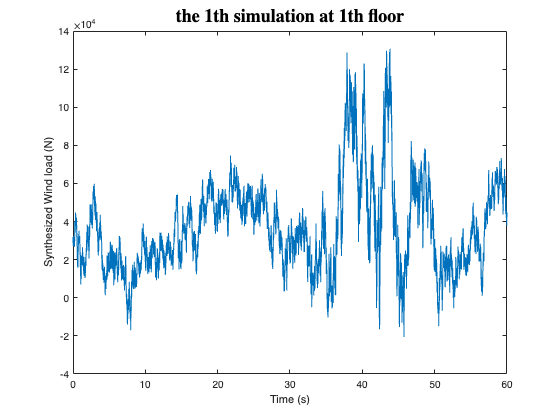

     5



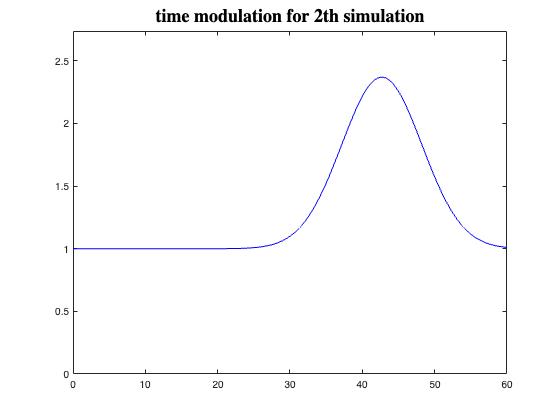

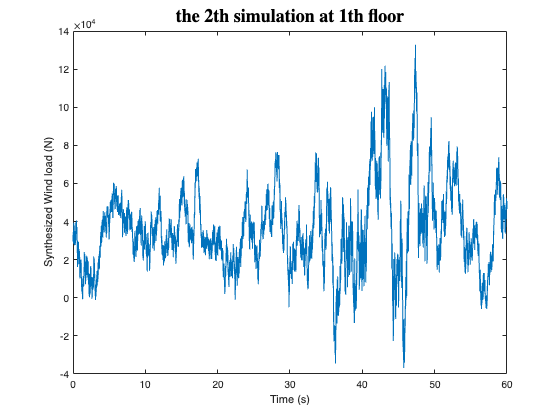

     5



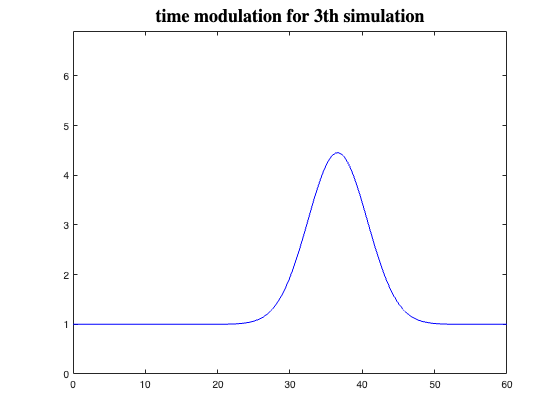

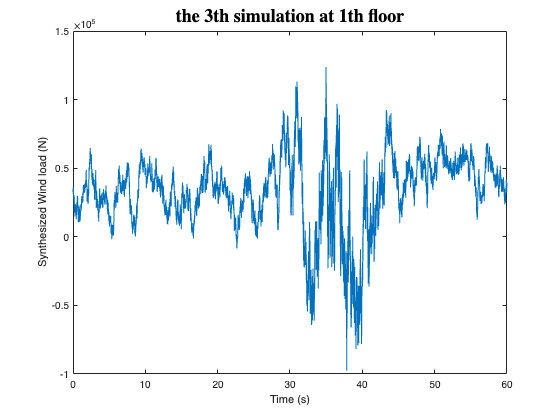

     5



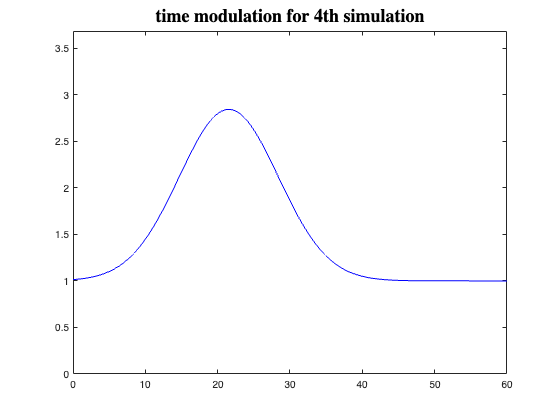

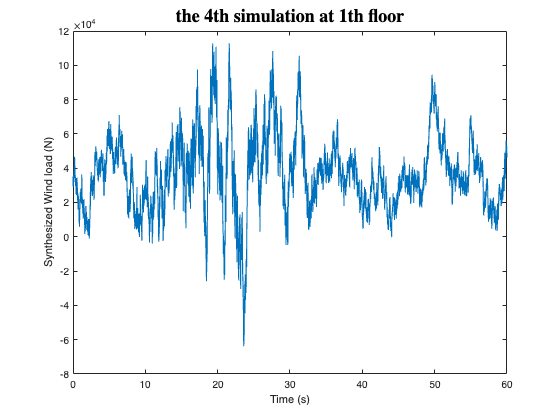

     5



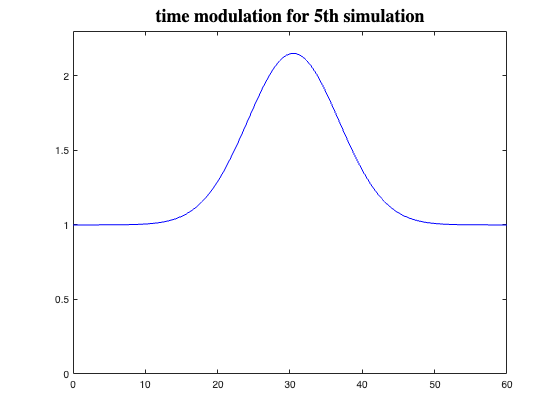

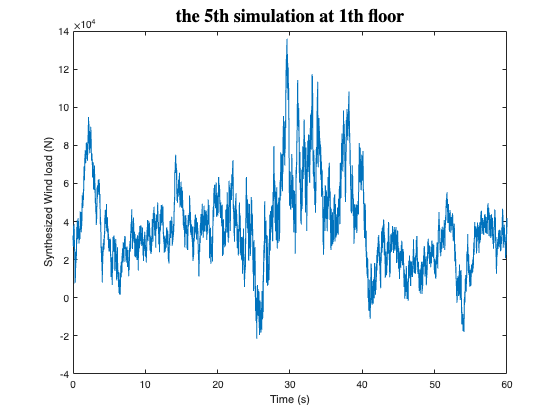

% mean square erros of nDOF

sigmaw = zeros(nDOF,1);
% ur us uz already defined
% safety factor
u = 2; % can be modified (2~2.5)

% pulsating amplification factor
uf = zeros(nDOF,1);

for j = 1:nDOF
    uf(j) = 0.5*35^(1.9*(alpha-0.16))*(H(j)/10)^(-alpha);
end

% mean squre error of nDOF
sigmaw = uf.*uz.*us*ur*w0/u;

% correlation matrix
Cor = zeros(nDOF,nDOF);
for k = 1:nDOF
    for j = 1:nDOF
        Cor(k,j) = exp(-1*sqrt((H(k)-H(j))^2)/60);
    end
end

p = 5; % order of AR model

% list of R - RL
RL = []; %zeros(nDOF*(p+1),nDOF) - required building block of the equation

for k = 0:p
    RL = [RL;R(k,SimStep,nDOF,fv,Sdf,Cor,sigmaw)];
end

% factor matrix of R - RF (RHS factor matrix in formula 5)
R0 = RL(1:nDOF,:);
RF = [R0];
for i = 1:p-1
    Ru = RL(nDOF+1:(i+1)*nDOF,:)';
    Rl = RL(nDOF+1:(i+1)*nDOF,:);
    RF = [R0,Ru; Rl,RF];
end

% column matrix of R - RC (LHS matrix in formula 5)
RC = RL(nDOF+1:end,:);

% Auto Regresssion Factor Matrix (according to formula 6)

PHI = inv(RF)*RC;

PHI(find(abs(PHI)<1e-8)) = 0; % if you investigate the original PHI, only the elements on diagnal matter 

% RN = covariance of the factors before the random shock term in AR model
RN = RL(1:nDOF,:);
for i = 1:p
    RN = RN - PHI((i-1)*nDOF+1:i*nDOF,:)*RL((i-1)*nDOF+1:i*nDOF,:);
end

% factor matrix before the random shock term in AR model
SigmaN = chol(RN,'lower');

% strong wind signal generation
for s = 1:NumSeg
    % current progress
    if i/(NumSeg/5) == fix(i/(NumSeg/5))
        disp(i)
    end

    ExcitationWindDynamic = zeros(seg,nDOF);

    %% excitation genration
    % initialization
        ExcitationWindDynamic(1:p,:) = normrnd(0,1,p,nDOF)*SigmaN;

    % excitation generation
    for j = p+1:seg
        ExcitationWindDynamic(j,:) = normrnd(0,1,1,nDOF)*SigmaN;
        for k = 1:p
            ExcitationWindDynamic(j,:) = ExcitationWindDynamic(j,:) + ExcitationWindDynamic(j-k,:)*PHI((k-1)*nDOF+1:k*nDOF,:);
        end
    end
    
    %disp('time areas');
    % from wind pressure to wind load
    for k = 1:seg
        ExcitationWindDynamic(k,:) = ExcitationWindDynamic(k,:).*Area';
    end

    % visualization of dynamic wind load
    % if flg_img_show == 1
    %     disp('visualization')
    %     figure;
    %     for j = 1:nDOF
    %         subplot(nDOF, 1, j)
    %         plot([1:1:seg]*SimStep, ExcitationWindDynamic(:, j))
    %         xlabel('Time (s)');
    %         ylabel('Dynamic Wind load (N)')
    %         title(['Floor ' num2str(j)])
    %     end
    % end

    % figure
    % disp(s)
    % disp(' th segment')
    % plot(ExcitationWindDynamic)
    % title('dynamic wind load')

    % % check the frequency domain distribution
    % 
    % % Set the parameters for pwelch
    % window = 2048; % window size
    % noverlap = 1024; % overlap between windows
    % nfft = 1024; % number of points for FFT
    % 
    % % Compute the PSD using pwelch
    % [Pxx,ff] = pwelch(WindowExcitation,window,noverlap,nfft);
    % 
    % % Plot the PSD
    % figure
    % plot(log10(ff),log10(Pxx))
    % xlabel('Frequency log(ff) (Hz)')
    % ylabel('PSD')
    % title('Power Spectral Density of the generated dynamic wind loaddata')

    % time domain modulation
    % as we used stationary method, which does not meet the requirement of
    % suddenevent monitoring here, we need to modify it to simulate the sudden
    % event like tornado or windstorm

    % we can use a envelope function to reshape the excitation

    % centers of the strong wind
    Miu = randi([round(0.2*seg),round(0.8*seg)],1);

    % standard deviation of strong wind events duration
    SigWind = 4+3*rand(1);

    % scale factor of strong wind events
    WindScale = 2+2*rand(1);
    FactorWind = (0.3+0.7*rand(1))*WindScale;

    ScaleWind = ones(seg,1);
    %disp('time modulation');
    
    ScaleWind = ScaleWind + FactorWind.*exp(-(TimeSeries'-Miu*SimStep).^2/2/SigWind^2);

    if flg_img_show == 1 && s/(NumSeg/5) == fix(s/(NumSeg/5))
        figure
        plot(TimeSeries,ScaleWind,'b-')
        axis([0,SimStep*seg,0,2*max(FactorWind)])
        Title = ['time modulation for ',num2str(s),'th simulation' ];
        title(Title,'FontName','Times New Rome','FontSize',18)
    end

    for j = 1:nDOF
        ExcitationWindDynamic(:,j) = ExcitationWindDynamic(:,j).*ScaleWind;
    end

    %% Synthesization
    WindowExcitation = ExcitationWindStatic + ExcitationWindDynamic;

    % input excitation integration
    for j = 1:nDOF
        Excitation_WD(s,j,:) = squeeze(WindowExcitation(:,j))/me; % note here the force is converted into acceleration by dividing me. 
    end

    % Check synthesized data
    % if flg_img_show == 1 && i/(NumSeg/5) == fix(i/(NumSeg/5))
    %     figure;
    %     for j = 1:nDOF
    %         subplot(nDOF, 1, j)
    %         plot(SimStep:SimStep:SimStep*seg, WindowExcitation(:, j))
    %         xlabel('Time (s)')
    %         ylabel('Synthesized Wind load (N)')
    %         Title = ['Floor ' num2str(j)];
    %         title(Title,'FontName','Times New Rome','FontSize',18)
    %     end
    % end
    if flg_img_show == 1 && s/(NumSeg/5) == fix(s/(NumSeg/5))
        figure;
        plot(SimStep:SimStep:SimStep*seg, WindowExcitation(:, 1))
        xlabel('Time (s)')
        ylabel('Synthesized Wind load (N)')
        Title = ['the ' num2str(s) 'th simulation ' 'at 1th floor'];
        title(Title,'FontName','Times New Rome','FontSize',18)
    end
end


disp('Strong Wind Generation Finished')

Strong Wind Generation Finished



size(Excitation_WD)

ans =            5           5       12000


fn_tmp = 'Excitation_WD.mat';
save(fn_tmp,'Excitation_WD')

## 5 Data Process for Simulation

TS_AV = [];
TS_EQ = [];
TS_IP = [];
TS_WD = [];

for i = 1:NumSeg
    for j = 1:nDOF
        SEG_AV(:,j) = squeeze(Excitation_AV(i,j,:));
        SEG_EQ(:,j) = squeeze(Excitation_EQ(i,j,:));
        SEG_IP(:,j) = squeeze(Excitation_IP(i,j,:));
        SEG_WD(:,j) = squeeze(Excitation_WD(i,j,:));
    end
    TMPTS_AV = timeseries(SEG_AV,TimeSeries);
    TMPTS_EQ = timeseries(SEG_EQ,TimeSeries);
    TMPTS_IP = timeseries(SEG_IP,TimeSeries);
    TMPTS_WD = timeseries(SEG_WD,TimeSeries);

    TS_AV{i} = TMPTS_AV;
    TS_EQ{i} = TMPTS_EQ;
    TS_IP{i} = TMPTS_IP;
    TS_WD{i} = TMPTS_WD;
end

% check data size
size(TS_AV)

ans =      1     5


size(TS_EQ)

ans =      1     5


size(TS_IP)

ans =      1     5


size(TS_WD)

ans =      1     5


save workspace_a.mat

**Appendix - Method for wind generation before time modulation**

**Auto Regression Method for Wind Simulation**

Assume the pulsating wind pressure can be expressed as the following formula, the wind pressure at the current point can be formulated by previous values and a random shock process with corresponding coefficients.

$w\left(t\right)=\sum_{k=1}^p \Psi_k w\left(t-k\Delta t\right)+\sigma^N N\left(t\right)$      ---(1)

Where$\;t$ is the current time, $\Delta t$ is the time series inverval, $w\left(t\right)$ is the pulsating wind vector, $w_i \left(t\right)$ is the ith entry in the vector, $\Psi_k$ is the coefficient matrix, $w\left(t-k\Delta t\right)$ is the wind vector at time $t-k\Delta t$,$\sigma^N$ is the coefficient matrix for the shock term, $N\left(t\right)$ is a vector corresponding to n stochastic process following a zero mean & 1 variance normal distribution.

$w\left(t\right)=\left\lbrack w_i \left(t\right)\right\rbrack =\left\lbrack \begin{array}{c}
w_1 \left(t\right)\\
\ldotp \\
w_i \left(t\right)\\
\ldotp \\
w_n \left(t\right)
\end{array}\right\rbrack$: n x 1

$\Psi_k =\left\lbrack \varphi_{\textrm{ij}}^k \right\rbrack =\left\lbrack \begin{array}{ccccc}
\varphi_{11}^k  & \ldotp  & \varphi_{1j}^k  & \ldotp  & \varphi_{1n}^k \\
\ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp \\
\varphi_{i1}^k  & \ldotp  & \varphi_{\textrm{ij}}^k  & \ldotp  & \varphi_{\textrm{in}}^k \\
\ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp \\
\varphi_{n1}^k  & \ldotp  & \varphi_{\textrm{nj}}^k  & \ldotp  & \varphi_{\textrm{nn}}^k 
\end{array}\right\rbrack$:n x n

$w\left(t-k\Delta t\right)=\left\lbrack w_i \left(t-k\Delta t\right)\right\rbrack =\left\lbrack \begin{array}{c}
w_1 \left(t-k\Delta t\right)\\
\ldotp \\
w_i \left(t-k\Delta t\right)\\
\ldotp \\
w_n \left(t-k\Delta t\right)
\end{array}\right\rbrack$: n x 1

$\sigma^N =\left\lbrack \sigma_{\textrm{ij}}^N \right\rbrack =\left\lbrack \begin{array}{ccccc}
\sigma_{11}^N  & \ldotp  & \sigma_{1j}^N  & \ldotp  & \sigma_{1n}^N \\
\ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp \\
\sigma_{\textrm{i1}}^N  & \ldotp  & \sigma_{\textrm{ij}}^N  & \ldotp  & \sigma_{\textrm{in}}^N \\
\ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp \\
\sigma_{n1}^N  & \ldotp  & \sigma_{\textrm{nj}}^N  & \ldotp  & \sigma_{\textrm{nn}}^N 
\end{array}\right\rbrack$ : n x n

$N\left(t\right)=\left\lbrack N_i \left(t\right)\right\rbrack =\left\lbrack \begin{array}{c}
N_1 \left(t\right)\\
\ldotp \\
N_i \left(t\right)\\
\ldotp \\
N_n \left(t\right)
\end{array}\right\rbrack$: n x 1

so the key is to calculate $\Psi_{\mathit{\mathbf{k}}}$ and $\sigma^N$, to do that, let's investigate the covariance of $w\left(t\right)$

for lag of $m\Delta t$


$$R\left(m\Delta t\right)=E\left\lbrack \left(w\left(t\right)-E\left(w\left(t\right)\right)\right)*{\left(w\left(t-m\Delta t\right)-E\left(w\left(t-m\Delta t\right)\right)\right)}^T \right\rbrack$$


here we assume the average of $w\left(t\right)$ is zero, same for $w\left(t-m\Delta t\right)$, then$E\left(w\left(t\right)\right)=$$E\left(w\left(t-R\left(m\Delta t\right)\right)\right)=0$

then 

$\begin{array}{l}
R\left(m\Delta t\right)\\
=E\left\lbrack \left(w\left(t\right)\right)*{\left(w\left(t-m\Delta t\right)\right)}^T \right\rbrack \\
=E\left(\left\lbrack \begin{array}{c}
w_1 \left(t\right)\\
\ldotp \\
w_i \left(t\right)\\
\ldotp \\
w_n \left(t\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{ccccc}
w_1 \left(t-k\Delta t\right) & \ldotp  & w_j \left(t-k\Delta t\right) & \ldotp  & w_n \left(t-k\Delta t\right)
\end{array}\right\rbrack \right)\\
=E\left(\left\lbrack \begin{array}{ccccc}
w_1 \left(t\right)w_1 \left(t-k\Delta t\right) & \ldotp  & w_1 \left(t\right)w_j \left(t-k\Delta t\right) & \ldotp  & w_1 \left(t\right)w_n \left(t-k\Delta t\right)\\
\ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp \\
w_i \left(t\right)w_1 \left(t-k\Delta t\right) & \ldotp  & w_i \left(t\right)w_j \left(t-k\Delta t\right) & \ldotp  & w_i \left(t\right)w_n \left(t-k\Delta t\right)\\
\ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp \\
w_n \left(t\right)w_1 \left(t-k\Delta t\right) & \ldotp  & w_n \left(t\right)w_j \left(t-k\Delta t\right) & \ldotp  & w_n \left(t\right)w_n \left(t-k\Delta t\right)
\end{array}\right\rbrack \right)\\
=E\left(\left\lbrack w_i \left(t\right)w_j \left(t-k\Delta t\right)\right\rbrack \right)\\
=E\left\lbrack \left(\sum_{k=1}^p \Psi_k w\left(t-k\Delta t\right){*\left(w\left(t-m\Delta t\right)\right)}^T +\sigma^N N\left(t\right)*{\left(w\left(t-m\Delta t\right)\right)}^T \right)\right\rbrack \\
=\;\sum_{k=1}^p \Psi_k E\left(w\left(t-k\Delta t\right){*\left(w\left(t-m\Delta t\right)\right)}^T \right)+\sigma^N E\left(N\left(t\right)*{\left(w\left(t-m\Delta t\right)\right)}^T \right)
\end{array}$ ---(2)

as $E\left(N\left(t\right)\right)$= 0

$\begin{array}{l}
R\left(m\Delta t\right)\;\\
=\sum_{k=1}^p \Psi_k E\left(w\left(t-k\Delta t\right){*\left(w\left(t-m\Delta t\right)\right)}^T \right)\\
=\sum_{k=1}^p \Psi_k R\left(\left(k-m\right)\Delta t\right)\\
=\left\lbrack \begin{array}{ccccc}
\Psi_1  & \ldotp  & \Psi_k  & \ldotp  & \Psi_p 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
R\left(\left(1-m\right)\Delta t\right)\\
\ldotp \\
R\left(\left(k-m\right)\Delta t\right)\\
\ldotp \\
R\left(\left(p-m\right)\Delta t\right)
\end{array}\right\rbrack 
\end{array}$ ---(3)

note that $R\left(m\Delta t\right)=R\left(-m\Delta t\right)$

similarly we can derive the expression for $R\left(\Delta t\right)\;,R\left(2\Delta t\right)\;\ldotp \ldotp \ldotp R\left(p\Delta t\right)\;$, (m = 1~p), then

${\left\lbrack \begin{array}{ccccc}
R\left(1\Delta t\right) & \ldotp  & R\left(m\Delta t\right)\; & \ldotp  & R\left(p\Delta t\right)
\end{array}\right\rbrack }_{\textrm{nxnp}} \;={\left\lbrack \begin{array}{ccccc}
\Psi_1  & \ldotp  & \Psi_k  & \ldotp  & \Psi_p 
\end{array}\right\rbrack }_{\textrm{nxnp}} {\left\lbrack \begin{array}{ccccc}
R\left(0\Delta t\right) & R\left(1\Delta t\right) & \ldotp  & R\left(\left(p-2\right)\Delta t\right) & R\left(\left(p-1\right)\Delta t\right)\\
R\left(1\Delta t\right) & R\left(0\Delta t\right) & R\left(1\Delta t\right) & \ldotp  & R\left(\left(p-2\right)\Delta t\right)\\
\ldotp  & R\left(1\Delta t\right) & R\left(0\Delta t\right) & R\left(1\Delta t\right) & \ldotp \\
R\left(\left(p-2\right)\Delta t\right) & \ldotp  & R\left(1\Delta t\right) & R\left(0\Delta t\right) & R\left(1\Delta t\right)\\
R\left(\left(p-1\right)\Delta t\right) & R\left(\left(p-2\right)\Delta t\right) & \ldotp  & R\left(1\Delta t\right) & R\left(0\Delta t\right)
\end{array}\right\rbrack }_{\textrm{npxnp}} \;$ ---(4)

if we assume $R\left(m\Delta t\right)\;$is symmetric, $\Psi_k$ is symmetric, we can derive that

${\left\lbrack \begin{array}{c}
R\left(1\Delta t\right)\\
\ldotp \\
R\left(m\Delta t\right)\;\\
\ldotp \\
R\left(p\Delta t\right)
\end{array}\right\rbrack }_{\textrm{npxn}} ={\left\lbrack \begin{array}{ccccc}
R\left(0\Delta t\right) & R\left(1\Delta t\right) & \ldotp  & R\left(\left(p-2\right)\Delta t\right) & R\left(\left(p-1\right)\Delta t\right)\\
R\left(1\Delta t\right) & R\left(0\Delta t\right) & R\left(1\Delta t\right) & \ldotp  & R\left(\left(p-2\right)\Delta t\right)\\
\ldotp  & R\left(1\Delta t\right) & R\left(0\Delta t\right) & R\left(1\Delta t\right) & \ldotp \\
R\left(\left(p-2\right)\Delta t\right) & \ldotp  & R\left(1\Delta t\right) & R\left(0\Delta t\right) & R\left(1\Delta t\right)\\
R\left(\left(p-1\right)\Delta t\right) & R\left(\left(p-2\right)\Delta t\right) & \ldotp  & R\left(1\Delta t\right) & R\left(0\Delta t\right)
\end{array}\right\rbrack }_{\textrm{npxnp}} {\left\lbrack \begin{array}{c}
\Psi_1 \\
\ldotp \\
\Psi_k \\
\ldotp \\
\Psi_p 
\end{array}\right\rbrack }_{\textrm{npxn}}$--(5)

if ${\left\lbrack \begin{array}{ccccc}
R\left(0\Delta t\right) & R\left(1\Delta t\right) & \ldotp  & R\left(\left(p-2\right)\Delta t\right) & R\left(\left(p-1\right)\Delta t\right)\\
R\left(1\Delta t\right) & R\left(0\Delta t\right) & R\left(1\Delta t\right) & \ldotp  & R\left(\left(p-2\right)\Delta t\right)\\
\ldotp  & R\left(1\Delta t\right) & R\left(0\Delta t\right) & R\left(1\Delta t\right) & \ldotp \\
R\left(\left(p-2\right)\Delta t\right) & \ldotp  & R\left(1\Delta t\right) & R\left(0\Delta t\right) & R\left(1\Delta t\right)\\
R\left(\left(p-1\right)\Delta t\right) & R\left(\left(p-2\right)\Delta t\right) & \ldotp  & R\left(1\Delta t\right) & R\left(0\Delta t\right)
\end{array}\right\rbrack }_{\textrm{npxnp}}$is full-rank, then we can derive

${\left\lbrack \begin{array}{c}
\Psi_1 \\
\ldotp \\
\Psi_k \\
\ldotp \\
\Psi_p 
\end{array}\right\rbrack }_{\textrm{npxn}} ={\left\lbrack \begin{array}{ccccc}
R\left(0\Delta t\right) & R\left(1\Delta t\right) & \ldotp  & R\left(\left(p-2\right)\Delta t\right) & R\left(\left(p-1\right)\Delta t\right)\\
R\left(1\Delta t\right) & R\left(0\Delta t\right) & R\left(1\Delta t\right) & \ldotp  & R\left(\left(p-2\right)\Delta t\right)\\
\ldotp  & R\left(1\Delta t\right) & R\left(0\Delta t\right) & R\left(1\Delta t\right) & \ldotp \\
R\left(\left(p-2\right)\Delta t\right) & \ldotp  & R\left(1\Delta t\right) & R\left(0\Delta t\right) & R\left(1\Delta t\right)\\
R\left(\left(p-1\right)\Delta t\right) & R\left(\left(p-2\right)\Delta t\right) & \ldotp  & R\left(1\Delta t\right) & R\left(0\Delta t\right)
\end{array}\right\rbrack }_{\textrm{npxnp}}^{-1} {\left\lbrack \begin{array}{c}
R\left(1\Delta t\right)\\
\ldotp \\
R\left(m\Delta t\right)\;\\
\ldotp \\
R\left(p\Delta t\right)
\end{array}\right\rbrack }_{\textrm{npxn}}$ ---(6)

In summary, we can calculate $\Psi_1$~$\Psi_p$, if we can calculate $R\left(m\Delta t\right)$, m is from 0 ~ p

as for $\sigma^N$, let's investigate the equation below first

$R^N =R\left(0\right)-\sum_{m=1}^p \Psi_m R\left(m\Delta t\right)\;$ ---(7)

do Cholesky decomposition to $R^N$ and we can take the lower decomposition of $R^N$ as $\sigma^N$

$R^N =\sigma^N {\sigma^N }^T$---(8)

note that for $\sigma_{\textrm{ij}}^N$, when i < j, $\sigma_{\textrm{ij}}^N =0$

now, let's look at how to calculate $R\left(m\Delta t\right)\;$

$R\left(m\Delta t\right)\;={\left\lbrack \begin{array}{c}
\;R_{\textrm{ij}} \left(m\Delta t\right)
\end{array}\right\rbrack }_{\textrm{nxn}} ={\left\lbrack \begin{array}{ccccc}
R_{11} \left(m\Delta t\right) & \ldotp  & R_{1j} \left(m\Delta t\right) & \ldotp  & R_{1n} \left(m\Delta t\right)\\
\ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp \\
R_{i1} \left(m\Delta t\right) & \ldotp  & R_{\textrm{ij}} \left(m\Delta t\right) & \ldotp  & R_{\textrm{in}} \left(m\Delta t\right)\\
\ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp \\
R_{\textrm{n1}} \left(m\Delta t\right) & \ldotp  & R_{\textrm{nj}} \left(m\Delta t\right) & \ldotp  & R_{\textrm{nn}} \left(m\Delta t\right)
\end{array}\right\rbrack }_{\textrm{nxn}}$ ---(9)

$R_{\textrm{ij}} \left(m\Delta t\right)=\int_0^{\infty } S_{\textrm{ij}} \left(f\right)\cos \left(2\pi f*m\Delta t\right)\textrm{df}\;$---(10) 

in practice we may use summation rather than integration for convenience.

$S\left(f\right)$ here is the power spetrum density, we can use Davenport PSD, which is widely used in wind engineering

to calculate $S\left(f\right)$

$S\left(f\right)=\left\lbrack S_{\textrm{ij}} \left(f\right)\right\rbrack =\left\lbrack \begin{array}{ccccc}
S_{11} \left(f\right) & \ldotp  & S_{1j} \left(f\right) & \ldotp  & S_{1n} \left(f\right)\\
\ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp \\
S_{i1} \left(f\right) & \ldotp  & S_{\textrm{ij}} \left(f\right) & \ldotp  & S_{\textrm{in}} \left(f\right)\\
\ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp \\
S_{\textrm{n1}} \left(f\right) & \ldotp  & S_{\textrm{nj}} \left(f\right) & \ldotp  & S_{\textrm{nn}} \left(f\right)
\end{array}\right\rbrack$ ---(11)

$S_{\textrm{ij}} \left(f\right)=\rho_{\textrm{ij}} \sigma \left(z_i \right)\sigma \left(z_j \right)S_d \left(f\right)$ ---(12)

where

$\rho_{\textrm{ij}}$ is the correlation coefficient

$\rho_{\textrm{ij}} =e^{-{\left(\frac{{\left(z_j -z_i \right)}^2 }{L_z }\right)}^{\frac{1}{2}} }$ ---(13)

$\sigma \left(z_i \right)$ is the standard deviation of the pulsating wind load at height $z_i$; similar for $\sigma \left(z_j \right)$.

$\sigma \left(z\right)=\frac{\mu_f \left(z\right)\mu_z \left(z\right)\mu_s \left(z\right)\mu_r }{\mu }w_0$  -- (14)

$\mu_r$ is the recurrence coefficient, which is  1.1 here

$\mu_s \left(z\right)$ is the shape coefficient, which is 0.8+0.5 = 1.3 here (assume the building is of a square shape)

$\mu_z \left(z_i \right)$ is the height coefficient, $\mu_z \left(z_i \right)={\left(\frac{H\left(i\right)}{H_{10} }\right)}^{\beta }$， $\beta$ = 0.3 here

$\mu_f \left(z\right)$  is the ratio of pulsating wind over satic wind, which can be calculated by

$\mu_f \left(z\right)=0\ldotp 5\times {35}^{1\ldotp 9\times \left(\alpha -0\ldotp 16\right)} \times {\left(\frac{H\left(i\right)}{H_{10} }\right)}^{-\alpha }$--(15)

we take alpha = 0.16 here

$\mu$ is the safety factor, which is 2~2.5

$S_d \left(f\right)$ is the Davenport PSD

$S_d \left(f\right)=4K\bar{v_{10}^2 } \frac{x_0^2 }{{f\left(1+x_0^2 \right)}^{\frac{4}{3}} }$ ---(16)

$x_0 =\frac{1200f}{\bar{v_{10} } }$---(17)